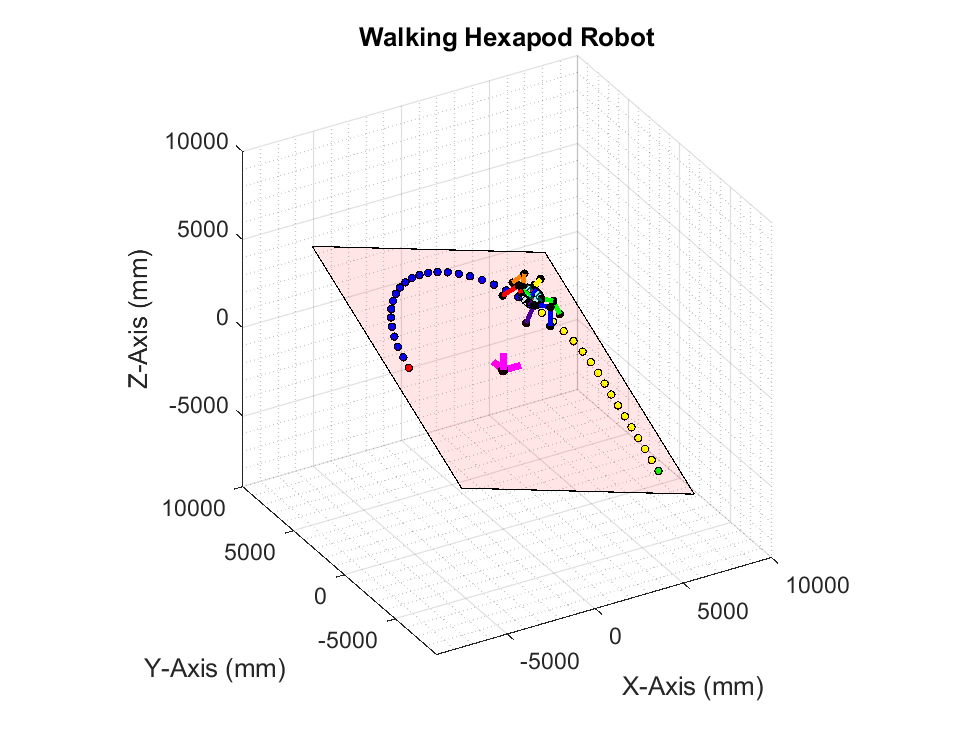

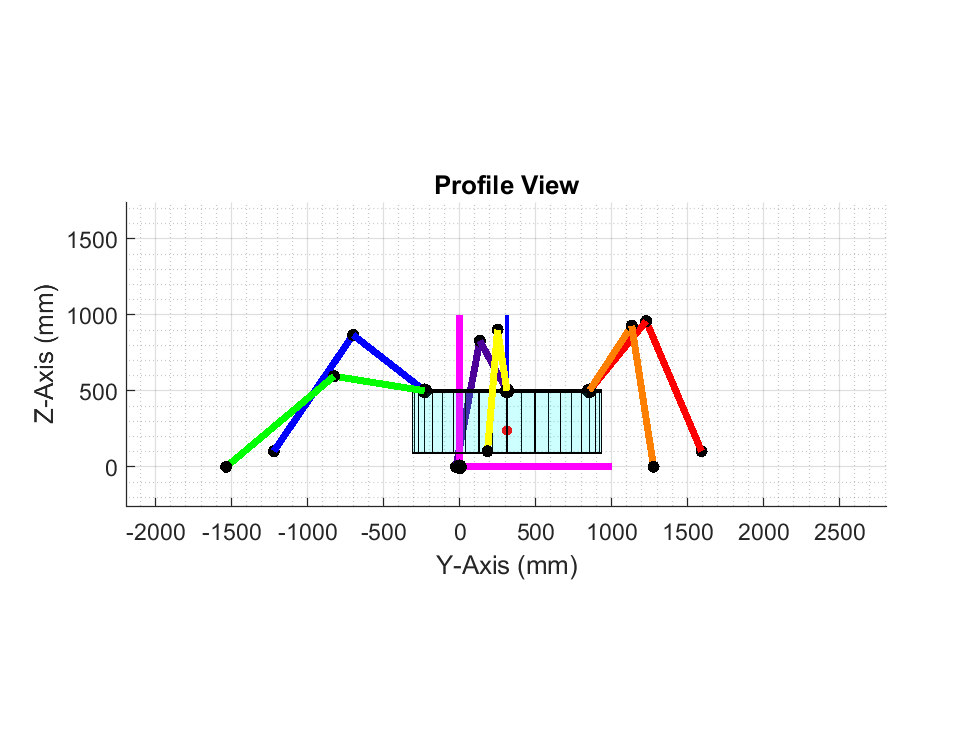

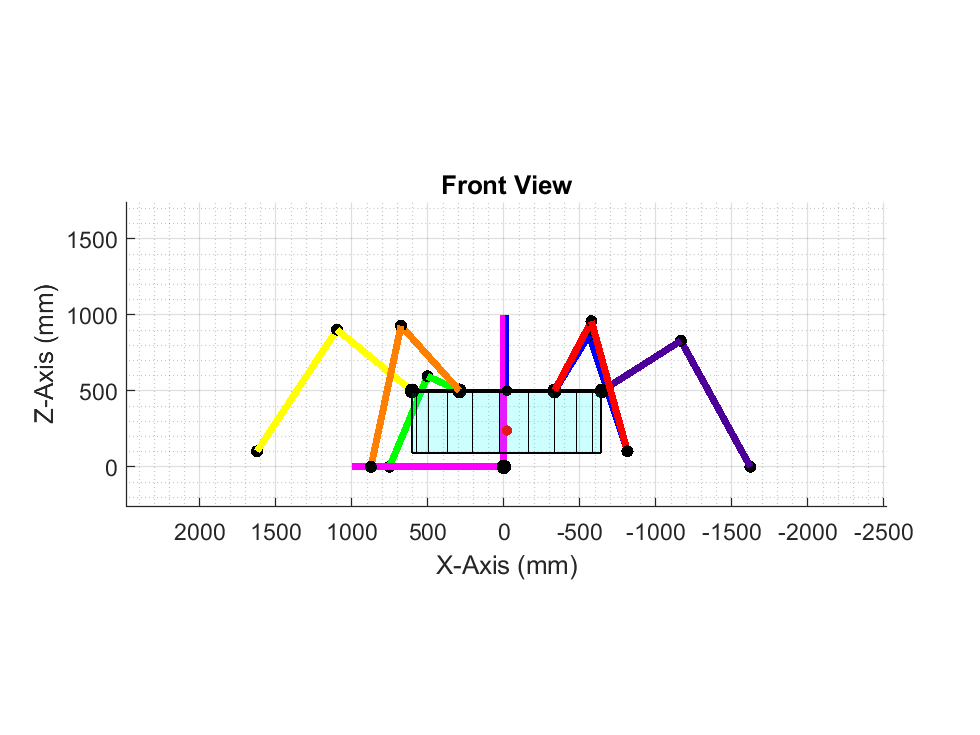

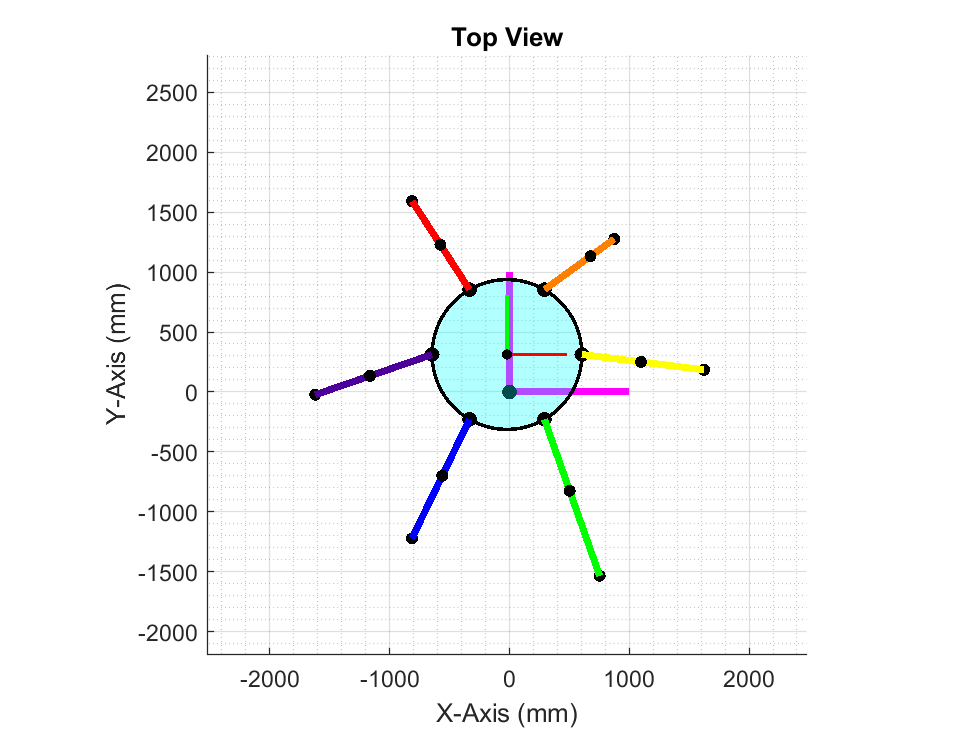

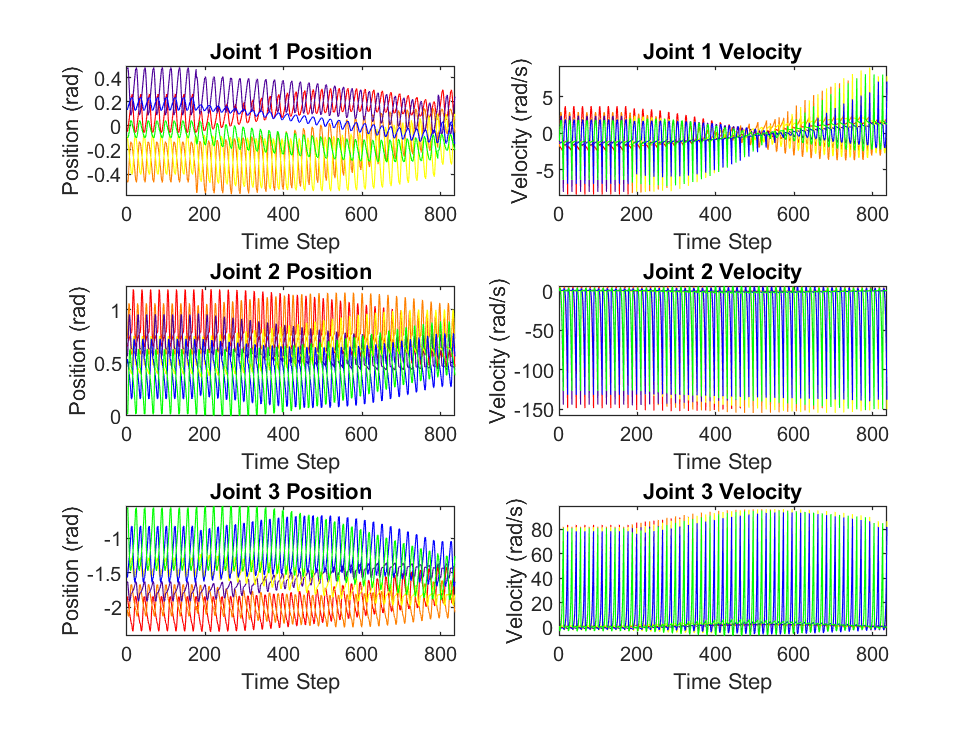

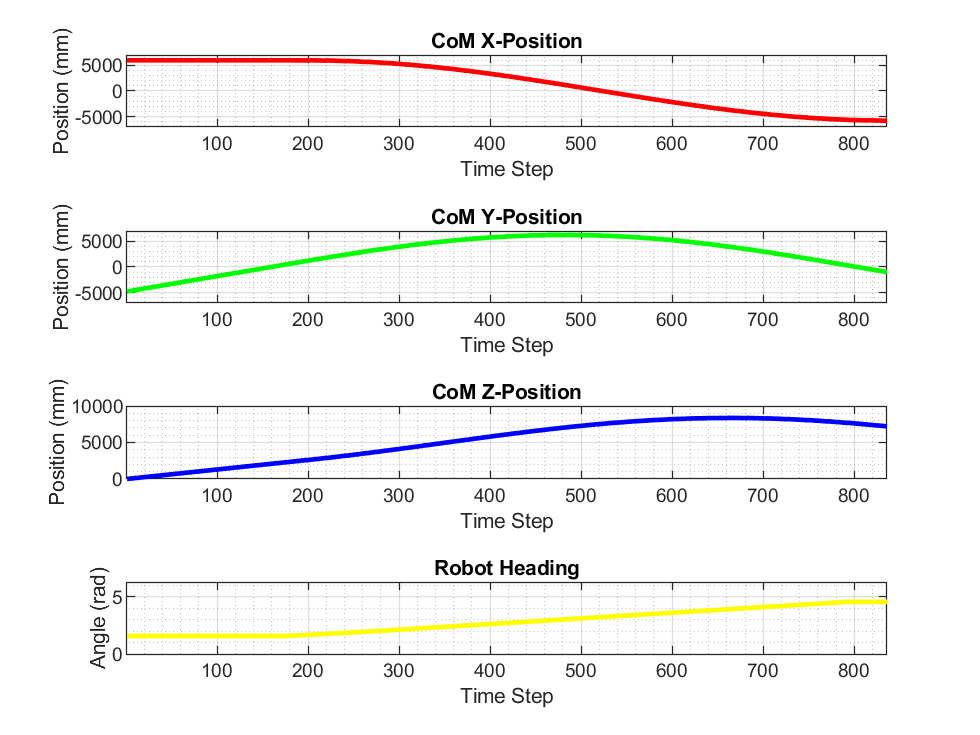

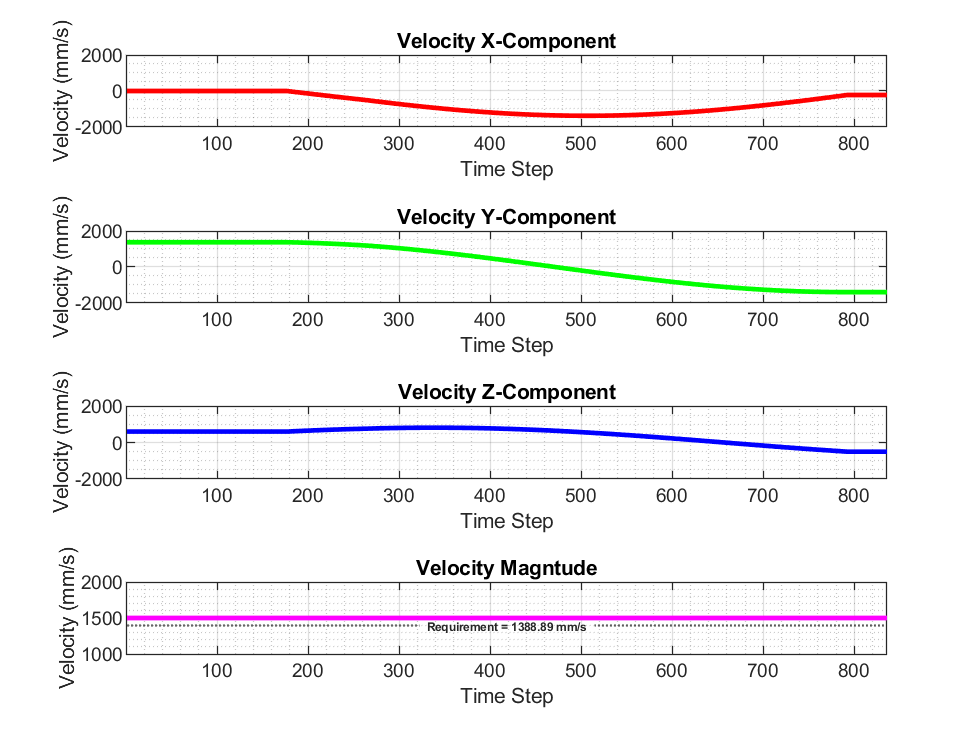

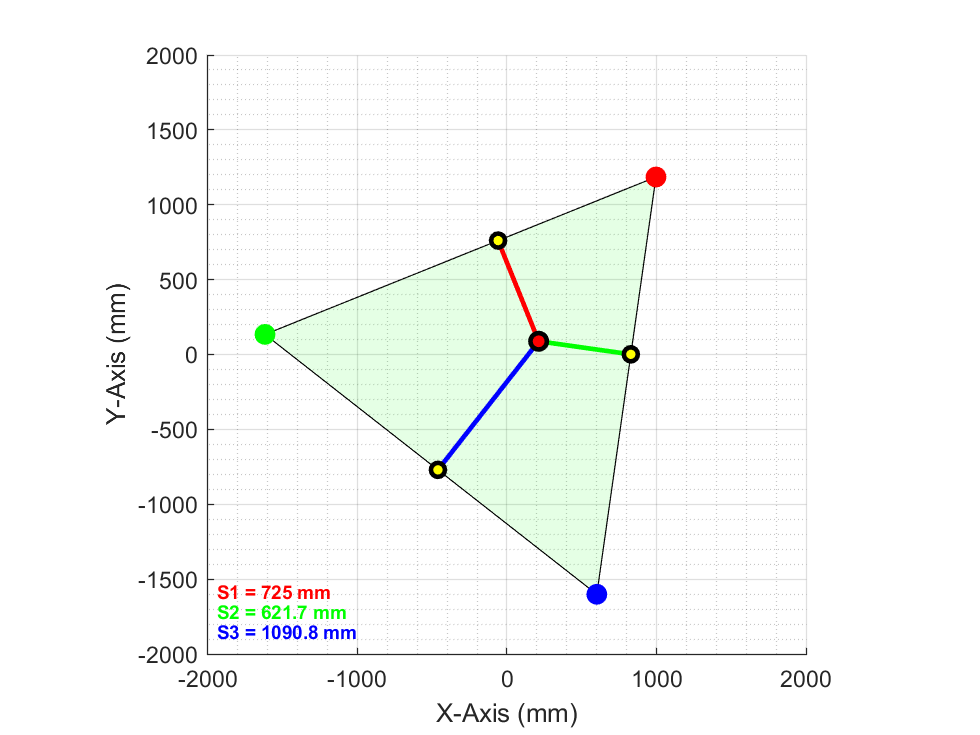

clf
clear
clc

%%% RBE 594 - Capstone Design Experience %%%
%%% Jason Munger %%%

%%% Robot Configuration Parameters: %%%
LL = 750; % Max Robot Stride length (mm)
v = 1500; % Desired velocity (mm/s)

r = 1625;       % home foot tip radius (mm)
B = 0.5;        % Duty factor (Tripod Gait)
h = 250;        % Max foot tip height off ground (mm)
offset = 375/2; % start position of support phase (mm)

beta = deg2rad(60); % leg orientation about CoM (rad)

% Leg attachment points in robot body frame:
s1 = [r*cos(2*beta), r*sin(2*beta)+offset, 0]';  % Leg 1
s2 = [r*cos(1*beta), r*sin(1*beta)+offset, 0]';  % Leg 2
s3 = [r*cos(3*beta), r*sin(3*beta)+offset, 0]';  % Leg 3
s4 = [r*cos(0*beta), r*sin(0*beta)+offset, 0]';  % Leg 4
s5 = [r*cos(4*beta), r*sin(4*beta)+offset, 0]';  % Leg 5
s6 = [r*cos(5*beta), r*sin(5*beta)+offset, 0]';  % Leg 6

s = [s1, s2, s3, s4, s5, s6]; % Combine into single matrix

CM = [0;0;-261]; % Center of mass of robot with respect to robot frame

% Load test trajectory data:
PP = load('Xdes.mat').Xdes; % Trajectory points and heading (mm; mm; rad)
PP = PP(1:2,:); % Trajectory X/Y coordinates (mm; mm)
Ldes = load('Ldes.mat').Ldes; % Desired robot strides between each waypoint along path (mm)
Rdes = load('Rdes.mat').Rdes; % Turn radius of each step (mm)
Xcdes = load('Xcdes.mat').Xcdes; % Turn radius center points in world frame (mm; mm)

newheading = 0; % new heading used for rotating in place (rad)
g0 = pi/2; % default robot heading in world frame (rad)

% Rotate in place (used to generate single step simulation):
% Xcdes = [0 0; 0 0];
% Rdes = [0,0];
% Ldes = [750,750];
% PP = [0 0;0 0];

% Walk straight (used to generate single step simulation):
% Xcdes = [-1e12 -1e12; 0 0]
% Rdes = [1e12,1e12];
% Ldes = [750,750];
% PP = [0 0;0 750]

%%% Set up simulation parameters %%% 
run_all = false; % run all visualization functions for all defined environments (bool)
animate = false; % choose whether to animate visuals (bool)
makeVideo = false; % create and export .avi video file (bool) -> animate must be set to true
save_fig = false; % choose whether to save generated figure (animate = false only)

% Visuals (set individual visuals to run if run_all set to false):
iso = true;                 % iso overview of robot walking along trajectory
profile = true;             % side view of robot walking in place 
front = true;               % front view of robot walking in place
top = true;                 % top view of robot walking in place
joints = true;              % visualize joint positions and velocites over trajectory
position = true;            % visualize robot global position and heading over trajectory
velocity = true;            % visualize robot velocity over trajecory
support_poly = true;        % visualize the support polygon of the robot
stability_margin = true;    % visualize the stability margin of the robot over the trajectory

visuals = [iso,profile,front,top,joints,position,velocity,support_poly,stability_margin];

frame = 350; % Set time step along trajectory to view (animate set to false) --> visualize specific locations along the trajectory

% Select environment to simulate (run_all set to false):
% env = 1 : Flat terrain (Rx = 0 deg, Ry = 0 deg)
% env = 2 : Incline Plane (Rx = 35 deg, Ry = 0 deg)
% env = 3 : Incline Plane (Rx = 23.5 deg, Ry = 23.5 deg)
env = 3; % Selected environment

num_tsteps = 11; % set number of time steps in the support and swing phases (total points per step = 2*num_tsteps)

% Gather robot parameters:
robotParams = [v, h, r, B, num_tsteps, newheading];

% Simulate the robot:
[Xworld, Vworld, Vrot,Vmag, CoM, leg_traj_full, leg_vel_full, Joint_Angles, joint_vel, RR, S1, U, F, Poses, SM,H,leg_pts,centroid ] = simulateRobot(run_all,env,animate,makeVideo,visuals, frame,PP, Ldes,Rdes,Xcdes, s,robotParams,g0,CM,save_fig);

# Robot Simulation Functions:

function [Xworld, Vworld, Vrot,Vmag, CoM, leg_traj_full, leg_vel_full, Joint_Angles, joint_vel, RR, S1, U, F, Poses, SM,H,leg_pts,centroid ] = simulateRobot(run_all,env,animate,makeVideo,visuals, frame,PP, Ldes,Rdes,Xcdes, s,robotParams,g0,CM,save_fig)
    
    %%% Simulate all environments and visuals %%%
    if run_all == true
        for i = 1:3
        
        env = i;
        
        if env == 1
            % Flat terrain:
            slopes = [0,0];
            P = [0;0;700;0;0;0];
            adaptiveCoM = false;
        elseif env == 2
            % Slope Rx:
            slopes = [35,0];
            P = [0;0;500;0;0;0];
            adaptiveCoM = true;
        elseif env == 3   
            % Slope Rx/Ry:
            slopes = [23.5,23.5];
            P = [0;0;500;0;0;0];
            adaptiveCoM = true;
        end
        
        %%% Robot walks over trajectory and collects configuation data at each time step %%%
        [Xworld, Vworld, Vrot,Vmag, CoM, leg_traj_full, leg_vel_full, Joint_Angles, joint_vel, RR, S1, U, F, Poses, SM,H,leg_pts,centroid ] = robotWalk(PP, Ldes,Rdes,Xcdes, s,robotParams,g0, P,CM,slopes, adaptiveCoM);
        
        num_tsteps = robotParams(5);
        
        %%% Visualize Robot %%%
        
        % 1) Iso View
        view_num = 0;
        visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate,makeVideo,frame, PP,num_tsteps, CM,save_fig)
        
        % 2) Profile View
        view_num = 1;
        visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate,makeVideo,frame, PP,num_tsteps, CM,save_fig)
        
        % 3) Front View
        view_num = 2;
        visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate,makeVideo,frame, PP,num_tsteps, CM,save_fig)
        
        % 4) Top View
        view_num = 3;
        visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate,makeVideo,frame, PP,num_tsteps, CM,save_fig)
        
        % 5) Robot Joints
        visualizeJoints(Joint_Angles, joint_vel,animate,makeVideo,slopes,save_fig)
        
        % 6) Robot Position
        visualizeRobotPosition(CoM,Xworld,animate,makeVideo,slopes,save_fig)

        % 7) Robot Velocity
        visualizeRobotVelocity(Vrot,Vmag,animate,makeVideo,slopes,save_fig)
        
        % 8) Support Polygon
        visualizeSupportPoly(leg_pts,centroid,H,SM,frame,animate,makeVideo,slopes,save_fig)
         
        % 9) Stability Margin
        visualizeStabilityMargin(SM,animate,makeVideo,slopes,save_fig)  
  
        end
    else
       
        %%% Simulate selected environment and visuals %%%
        if env == 1
            % Flat terrain:
            slopes = [0,0];
            P = [0;0;700;0;0;0];
            adaptiveCoM = false;
        elseif env == 2
            % Slope Rx:
            slopes = [35,0];
            P = [0;0;500;0;0;0];
            adaptiveCoM = true;
        elseif env == 3   
            % Slope Rx/Ry:
            slopes = [23.5,23.5];
            P = [0;0;500;0;0;0];
            adaptiveCoM = true;
        end
        

        num_tsteps = robotParams(5);
        
        %%% Robot walks over trajectory and collects configuation data at each time step %%%
        [Xworld, Vworld, Vrot,Vmag, CoM, leg_traj_full, leg_vel_full, Joint_Angles, joint_vel, RR, S1, U, F, Poses, SM,H,leg_pts,centroid ] = robotWalk(PP, Ldes,Rdes,Xcdes, s,robotParams,g0, P,CM,slopes, adaptiveCoM);

        %%% Visualize Robot %%%
        
         % 1) Iso View
        if visuals(1) == true
        view_num = 0;
        visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate,makeVideo,frame, PP,num_tsteps, CM,save_fig)
        end
        
        % 2) Profile View
        if visuals(2) == true
        view_num = 1;
        visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate,makeVideo,frame, PP,num_tsteps, CM,save_fig)
        end
        
        % 3) Front View
        if visuals(3) == true
        view_num = 2;
        visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate,makeVideo,frame, PP,num_tsteps, CM,save_fig)
        end
        
        % 4) Top View
        if visuals(4) == true
        view_num = 3;
        visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate,makeVideo,frame, PP,num_tsteps, CM,save_fig)
        end
        
        % 5) Robot Joints
        if visuals(5) == true
        visualizeJoints(Joint_Angles, joint_vel,animate,makeVideo,slopes,save_fig)
        end
        
        % 6) Robot Position
        if visuals(6) == true
        visualizeRobotPosition(CoM,Xworld,animate,makeVideo,slopes,save_fig)
        end
        
        % 7) Robot Velocity
        if visuals(7) == true
        visualizeRobotVelocity(Vrot,Vmag,animate,makeVideo,slopes,save_fig)
        end
        
        % 8) Support Polygon
        if visuals(8) == true
        visualizeSupportPoly(leg_pts,centroid,H,SM,frame,animate,makeVideo,slopes,save_fig)
        end
        
        % 9) Stability Margin
        if visuals(9) == true
        visualizeStabilityMargin(SM,animate,makeVideo,slopes,save_fig)
        
        end                       
    end
end

## Robot Walk Over Trajectory:

function [Xworld, Vworld, Vrot,Vmag, CoM, leg_traj_full, leg_vel_full, Joint_Angles, joint_vel, RR, S1, U, F, Poses, SM,H,leg_pts,centroid ] = robotWalk(PP, Ldes,Rdes,Xcdes, s,robotParams,g0,P,CM,slopes, adaptiveCoM)
    
    x = Xcdes(1,1);
    y = Xcdes(2,1);
    R = Rdes(1);
    LL = Ldes(1);
    P0 = PP(:,1)';
    P1 = PP(:,2)';
    
    genFootParams = [LL, R, x,y];
    
    % Initialize Variables
    Joint_Angles = [];
    Poses = [];
    Xworld = [];
    Vworld = [];
    S1 = [];
    RR = [];
    U = [];
    leg_traj_full = [];
    leg_vel_full = [];
    SM = [];
    H = [];
    leg_pts = [];
    centroid = [];
    j=1;

    for n = 2:length(PP)

        [traj_support, vel_support, traj_swing, vel_swing, params] = genFootTraj(P0,P1,s,genFootParams,robotParams,g0);
    
        R = params(1);
        w = params(2);
        xc = params(3);
        yc = params(4);
        Ts = params(5);
        Tt = params(6);
        t2 = params(7);
        g1 = params(8);
        g0 = params(9);
        
        % Move robot in space
        [X, V,head] = moveRobot(P0, params(1), params(2), params(5)+params(6), params(7),  g0, robotParams(5));
        
        % Gather robot configuration data
        Xworld = [Xworld,[X;head]];  % Collect robot global coordinates and heading
        Vworld = [Vworld, V];        % Collect robot velocitt in global frame
        
        % Synchronize leg trajectories based off selected walking gait:
        [leg_traj, leg_vel, leg_state] = syncLegs(traj_support, vel_support, traj_swing, vel_swing, 'tripod');
        
        % Collect leg trajectory data
        leg_traj_full = [leg_traj_full, leg_traj];
        leg_vel_full = [leg_vel_full, leg_vel];
        
        % Robot takes next step and outputs configuration data
        [RR, S1, ~, ~, ~, ~,U,F,j,Joint_Angles, Poses, SM,H,leg_pts,centroid]=takeStep(leg_traj,-t2,X,head,j,Joint_Angles, Poses, S1, RR, slopes, U,P,leg_state,CM, SM,H,leg_pts,centroid,adaptiveCoM);
      
        if n >= length(PP)
            break
        end
        
        % Set parameters for next step of trajectory
        P0 = PP(:,n)';
        P1 = PP(:,n+1)';
        x = Xcdes(1,n);
        y = Xcdes(2,n);
        R = Rdes(n);
        LL = Ldes(n);
        genFootParams = [LL, R, x,y];
        g0 = g1;
    
    end
    
    % Gather Robot Body Velocity Data
    rotm = Rotx(deg2rad(slopes(1)))*Roty(deg2rad(slopes(2)));
    Vrot = zeros(3,length(Vworld));
    Vrot(1:2,:) = Vworld;
    Vrot = rotm*Vrot;
    Vmag = vecnorm(Vrot);
    
    % Gather Robot Body Center of Mass in Global Frame
    xwrld = zeros(3,length(Xworld));
    xwrld(1:2,:) = Xworld(1:2,:);
    CoM = Poses(1:3,:) + CM;
    CoM = rotm*(CoM+xwrld);
    CoM(3,:) = CoM(3,:)-CoM(3,1);
    
    % Compute Joint Velocities
    joint_vel = getJointVel(Joint_Angles,leg_vel_full);
end

## **Synchronize Leg Foot Trajectories:**

function [leg_traj, leg_vel, leg_state] = syncLegs(traj_support, vel_support, traj_swing, vel_swing, gait )
    
    [~,c,num_legs] = size(traj_support);
    [~,d,~] = size(traj_swing);
    leg_traj = zeros(3,c+d, num_legs);
    leg_vel = zeros(3,c+d, num_legs);
    tags = {'support','swing'};
    group1_state = strings([num_legs/2,c+d]);
    group2_state = strings([num_legs/2,c+d]);
    leg_state = strings([num_legs, c+d]);
    
    if strcmp(gait,'tripod')
        group1 = [1,4,5];
        group2 = [2,3,6];
    
        group1_support = traj_support(:,:,group1);
        group2_support = traj_support(:,:,group2);
        group1_swing = traj_swing(:,:,group1);
        group2_swing = traj_swing(:,:,group2);
    
        group1_vel_support = vel_support(:,:,group1);
        group2_vel_support = vel_support(:,:,group2);
        group1_vel_swing = vel_swing(:,:,group1);
        group2_vel_swing = vel_swing(:,:,group2);
    
        g1 = [group1_support, group1_swing];
        group1_state(:,1:c) = tags{1};
        group1_state(:,c+1:end) = tags{2};
        g2 = [group2_swing, group2_support];
        group2_state(:,1:d) = tags{2};
        group2_state(:,d+1:end) = tags{1};
    
        leg_traj(:,:,group1) = g1;
        leg_traj(:,:,group2) = g2;
    
        leg_state(group1,:) = group1_state;
        leg_state(group2,:) = group2_state;
    
        gv1 = [group1_vel_support, group1_vel_swing];
        gv2 = [group2_vel_swing, group2_vel_support];
    
        leg_vel(:,:,group1) = gv1;
        leg_vel(:,:,group2) = gv2;
    
    end
end

## Take Single Step:

function [RR, S1, Pnew, alpha_i_rad, beta_i_rad, gamma_i_rad,U,F,j,Joint_Angles, Poses, SM,H,leg_pts,centroid]= takeStep(leg_traj,t2,X,head,j, Joint_Angles, Poses, S1, RR,slopes, U,P,leg_states,CM, SM,H,leg_pts,centroid, adaptiveCoM)
    % Desired Pose
    %     slope = 35;
    %     P = [0 0 650 0 0 0]';
    P;
    Rm = 625;
    Rf = Rm + 1000;
    %Euler Angle Representation
    euler = 'XYZ';
    L1 = 0;
    [r,c,num_legs] = size(leg_traj);
    for i = 1:c
        i;
        F = reshape(leg_traj(:,i,:),[r,num_legs]);
        if adaptiveCoM == true
            if (mod(i,c) > c/2) || (mod(i,c) == 0)
                id = 12;
            else
                id = 1;
            end
            
            FF =  reshape(leg_traj(:,id,:),[r,num_legs]);
            groundFeet = getFootTips(leg_states,FF,id);
            Pnew = updatePose(CM,P,groundFeet,slopes, head(i),t2);
        else
            Pnew = P;
        end
        gf = getFootTips(leg_states,F,i);
        [sm,h,legpts,cm] = stabilityMargin(Pnew,CM,gf, slopes, head(i));
        [l, L, l_prime, L_prime,s1, alpha_real, R,u,R_prime] = InvKinWalkfull(Pnew, euler, Rm, Rf, L1, F, slopes,t2);
        L;
        [alpha_i_rad, beta_i_rad, gamma_i_rad] = getJointAngles(l_prime, L_prime,L, alpha_real);
        Joint_Angles(:,:,j) = [alpha_i_rad'; beta_i_rad'; gamma_i_rad'];
        Poses(:,j) = Pnew;
        S1(:,:,j)=s1;
        RR(:,:,j)=R;
        U(:,:,j) = u;
        %         set(gcf,'Visible','on')
        angleCheck(alpha_i_rad, beta_i_rad, gamma_i_rad);
        x = [X(:,i);0];
        yaw = head(i);
        SM = [SM, sm];
        H = [H;h];
        leg_pts = [leg_pts;legpts];
        centroid = [centroid,cm];
        j = j+1;
    end
end

function groundFeet = getFootTips(leg_state,F,i)
    states = leg_state(:,i);
    idxs = strcmp(states,"support");
    groundFeet = F(:,idxs);
end

function Pnew = updatePose(CM,P,groundFeet,slopes, yaw,t2)
    
    Xaxis = [1;0;0];
    Yaxis = [0;1;0];
    angx = slopes(1);
    angy = slopes(2);
    angz = yaw-pi/2;
    
    Rx = Rotx(deg2rad(-angx));
    Ry = Roty(deg2rad(-angy));
    Rz = Rotz(angz);
    
    legs = groundFeet;
    legs = Rotz(t2)*legs;
    cm = triCentroid(legs(:,1),legs(:,2),legs(:,3));
    
    startCM = P(1:3)+CM;
    desiredCM = Rz*(cm + [0;0;startCM(3)]);
    rotdesCM = Rx*Ry*desiredCM;
    
    desCM= Rotz(-angz)*[dot(rotdesCM,Xaxis)/(cosd(angy));dot(rotdesCM,Yaxis)/(cosd(angx));startCM(3)];
    xshift = desCM(1)-startCM(1);
    yshift = desCM(2)-startCM(2);
    
    Pnew = [xshift;yshift;P(3:end)];

end

function cm = triCentroid(p1,p2,p3)

    xc = (p1(1)+p2(1)+p3(1))/3;
    yc = (p1(2)+p2(2)+p3(2))/3;
    zc = 0;
    cm = [xc,yc,zc]';

end

function [SM,H,Leg_pts,cm2] = stabilityMargin(P,CM,leg_points, slopes, yaw)

    cm = P(1:3)+CM;
    leg1 = leg_points(:,1);
    leg2 = leg_points(:,2);
    leg3 = leg_points(:,3);
    
    angx = slopes(1);
    angy = slopes(2);
    angz = yaw-pi/2;
    
    Rx = Rotx(deg2rad(angx));
    Ry = Roty(deg2rad(angy));
    Rz = Rotz(-angz);
    
    R = Rx*Ry;
    
    leg1 = Rz*leg1;
    leg2 = Rz*leg2;
    leg3 = Rz*leg3;
    
    cm = R*cm;
    cm2 = zeros(3,1);
    cm2(1) = cm(1)/cosd(slopes(2));
    cm2(2) = cm(2)/cosd(slopes(1));
    cm2 = Rz*cm2;
    
    s1 = polyarea([leg1(1),leg2(1),cm2(1)],[leg1(2),leg2(2),cm2(2)]);
    s2 = polyarea([leg1(1),leg3(1),cm2(1)],[leg1(2),leg3(2),cm2(2)]);
    s3 = polyarea([leg2(1),leg3(1),cm2(1)],[leg2(2),leg3(2),cm2(2)]);
    
    l1 = norm((leg2-leg1),2);
    l2 = norm((leg3-leg1),2);
    l3 = norm((leg3-leg2),2);
    
    h1 = (2*s1)/l1;
    h2 = (2*s2)/l2;
    h3 = (2*s3)/l3;
    
    a = leg1-cm2;
    c = leg3-cm2;
    b = leg2-cm2;
    
    A = norm((leg1-cm2),2);
    C = norm((leg3-cm2),2);
    B = norm((leg2-cm2),2);
    
    th1 = acos((dot(a,b))/(A*B));
    th3 = acos((dot(b,c))/(B*C));
    th2 = acos((dot(c,a))/(C*A));
    
    ph2 = acos(h2/A);
    ph1 = acos(h1/B);
    ph3 = acos(h3/C);
    
    stth = abs(atan2(leg2(2),leg2(1)));
    
    stth1 = atan((leg2(2)-cm2(2))/(leg2(1)-cm2(1)));
    if stth <pi/2
        Rz1 = Rotz(+stth1+ph1);
        Rz2 = Rotz(+stth1+th1+ph2);
        Rz3 = Rotz(+stth1+th1+th2+ph3);
    
    else
    
        Rz1 = Rotz(pi-(ph1-stth1));
        Rz2 = Rotz(pi-(th1-stth1)-ph2);
        Rz3 = Rotz(pi-(th1-stth1)-th2-ph3);
    
    end
    
    
    
    H1 = Rz1*[h1;0;0]+cm2;
    H2 = Rz2*[h2;0;0]+cm2;
    H3 = Rz3*[h3;0;0]+cm2;
    
    SM = [h1;h2;h3];
    H = [H1,H2,H3];
    
    Leg_pts = [leg1,leg2,leg3];
    % SM = min([h1,h2,h3]);

end

### Internal Functions used for Inverse Kinematics Calculations:

**Function to calculate **$\gamma_i$** for each leg**

function gamma = calcGamma(l2, l3, l_prime)
    
    gamma = [];
    
    for i = 1:6
        a = (l2^2 + l3^2 -l_prime(i)^2)/(2*l2*l3);
        b = -pi + acos(a);
        gamma = [gamma, b ];
    end
end

**Function to calculate **$\beta_i$** for each leg**

function [beta, phi] = calcBeta(l1, l2, l3, l_prime, L_prime, L)

    beta = [];
    phi = [];
    
    for i = 1:6
        a = (l2^2 + l_prime(i)^2 - l3^2)/(2*l2*l_prime(i));
        x = rssq([L_prime(1,i),L_prime(2,i)]);
        h_prime = L_prime(3,i);
        h = L(3,i);
        rho = atan(h_prime/x);
        if l1 ==0
            Phi = 0;
        else
            Phi = asin((h_prime - h)/l1);
        end
        %         Phi = asin((h_prime - h)/l1);
        phi = [phi, Phi];
        b = acos(a) - (rho + Phi);
        beta = [beta, b ];
    end
end

function [alpha_i_rad, beta_i_rad, gamma_i_rad] = getJointAngles(l_prime, L_prime,L, alpha_real)
    l1 = 0;
    l2 = 640; %Femur Segment Length
    l3 = 960; %Tibia Segment Length
    
    %Calculate Gamma
    gamma = calcGamma(l2, l3, l_prime);
    %Calculate Beta
    [beta, phi] =calcBeta(l1, l2, l3, l_prime, L_prime, L);
    beta = round(beta,4);
    
    %Joint Angles (degrees):
    alpha_i_deg = rad2deg(alpha_real)';
    beta_i_deg = rad2deg(beta)';
    gamma_i_deg = rad2deg(gamma)';
    joint_angles_deg = table(alpha_i_deg,beta_i_deg,gamma_i_deg);
    
    %Joint Angles (radians):
    alpha_i_rad = alpha_real';
    beta_i_rad = beta';
    gamma_i_rad = gamma';
end

function angleCheck(a, b, g)
    alpha_check = and((a>=-pi/4),(a<=pi/4));
    beta_check = and((b>=deg2rad(-38)),(b<=deg2rad(102)));
    gamma_check = and((g<=0),(g>=-3*pi/4));
    
    if alpha_check & beta_check & gamma_check
        %     disp('Pose is valid');
    else
        %     check = 'Pose is invalid';
        msg = 'Hexapod Walking Robot pose is invalid. One or more of the joint angles exceedes their limit(s).';
        error(msg)
    end
end

function joint_vel = getJointVel(joint_angles,leg_vel)

    [num_joints,num_legs,tsteps] = size(joint_angles);
    joint_vel = zeros(num_joints,num_legs,tsteps);
    
    for i = 1:tsteps
        for j = 1:num_legs
        J = jacobian(joint_angles(:,j,i));
        invJ = inv(J(1:3,1:3));
        jv = J(1:3,1:3)\leg_vel(:,i,j);
        joint_vel(:,j,i) = jv;
        end
    end
end

function J = jacobian(joint_ang)
    L1 = 0;
    L2 = 640;
    L3 = 960;
    
    % DH Parameters (a, alpha, d, theta:
    Leg_DH = [ L1,        pi/2,       0,         joint_ang(1);
               L2,           0,       0,         joint_ang(2);
               L3,           0,       0,         joint_ang(3)];
    
    A01 = DH_func(Leg_DH(1,1),Leg_DH(1,2),Leg_DH(1,3),Leg_DH(1,4));
    A12 = DH_func(Leg_DH(2,1),Leg_DH(2,2),Leg_DH(2,3),Leg_DH(2,4));
    A23 = DH_func(Leg_DH(3,1),Leg_DH(3,2),Leg_DH(3,3),Leg_DH(3,4));
    
    T01 = A01;
    T02 = T01*A12;
    T03 = T02*A23;
    
    % z-axes
    z0 = [0;0;1];
    z1 = T01(1:3,3);
    z2 = T02(1:3,3);
    
    % frame origins
    o0 = [0;0;0];
    o1 = T01(1:3,4);
    o2 = T02(1:3,4);
    o3 = T03(1:3,4);
    
    % indvidual Jacoobians [Jv (3x1); Jw (3x1)]
    J1 = [cross(z0, (o3-o0)); z0];
    J2 = [cross(z1, (o3-o1)); z1];
    J3 = [cross(z2, (o3-o2)); z2];
    
    % full Jacobian (6x6)
    J = [J1 J2 J3];
end

## Foot Trajectory Generation Function:

function [traj_support, vel_support, traj_swing, vel_swing, params] = genFootTraj(P0,P1,f, genFootParams,robotParams,g0)

    L = genFootParams(1);
    R = genFootParams(2);
    x = genFootParams(3);
    y = genFootParams(4);
    v = robotParams(1);
    h = robotParams(2);
    r = robotParams(3);
    B = robotParams(4);
    
    num_tsteps = robotParams(5);
    newheading = robotParams(6);
    % Inputs:
    % 1. initial robot foot coordinates (f)
    % 2. initial robot coordinate (P0)
    % 3. destination robot coordinate (P1)
    % 4. foot stride lenght (L)
    % 5. robot body velocity magnitude (v)
    % 6. foot height maximum (h)
    % 7. foot tip radius with respect to body COM
    % 8. gait duty cycle (B)
    % 9. current robot heading angle (heading)
    % 10. new robot heading angle (newheading) --> optional (used for
    % pure rotations about COM)
    
    % Outputs:
    % 1. foot tip trajectory of all n legs for support phase
    % 2. foot tip velocity of all n legs for support phase
    % 3. foot tip trajectory of all n legs for swing phase
    % 4. foot tip velocity of all n legs for swing phase
    % 5. collected gate parameters:
    % R - turn radius
    % w - robot body angular velocity
    % turn_center - [xc, yc] center coordinate of turn radius
    % direction - [NS, EW] turn directions ([North = 1, South = -1], [West = 1, East = -1])
    % T_gait - [Ts, Tt] gait cycle phase periods (support, swing/transfer)
    % t2 - heading of cirle center point defining the turn radius wrt to horizontal
    % g1 - heading of robot at destination point
    
    % 1. Get turn directions from initial to destination coordinates
    %     [NS, EW] = getDirections(P0,P1);
    
    %     c = rotDirection(P0,P1);
    %     g = atan2(P0(2),P0(1))
    %     if R <1e12
    %           g0 = g + c*(pi/2);
    %     end
    
    % 2. Calculate parameters defining the robot turning motion
    % [R, xc,yc,t2, g1] = calcTurnParams(P0,P1, heading, NS, EW);
    [ xc,yc,t2, g1, g0, dir, R] = calcTurnParams(P0,P1,g0, R,x,y);
    
    % 3. Calculate the necessary parameters to define the walking gait
    [w, Ts, Tt, ~] = getGaitParams(L, v, R, r, B, g0, dir, newheading);
    
    turn_center = [xc,yc];
    %     direction = [NS, EW];
    T_gait = [Ts, Tt];
    
    params = [R, w, turn_center, T_gait, t2, g1, g0]; % Gather misc. parameters to use outside function
    %     num_tsteps = 21;
    t = linspace(0,Ts,num_tsteps); % divide period into time steps
    num_legs = length(f); % get number of legs of robot
    traj_support = zeros(3,length(t), num_legs); % initialize trajectory matrix
    vel_support = zeros(3,length(t), num_legs); % initialize velocity matrix
    
    %%% SUPPORT PHASE %%%
    % Loop through all foot tip locations and calculate support phase
    % trajectory. Store in 3D matrix for future use.
    % if theta == inf
    %     rot_ang = g0
    % else
    %     rot_ang = g0-pi/2
    % end
    rot_ang = g0-pi/2;
    
    f_rot = Rotz(rot_ang)*f;
    
    for n = 1:num_legs
    
        %%% Foot Tip Position %%%
        xA = f_rot(1,n); % get current x-coordinate of foot n
        yA = f_rot(2,n); % get current y-coordinate of foot n
    
        Tx = R.*(1-cos(-t2+w.*t));   % calculate x-component of translation operator
        Ty = R.*sin(-t2+w.*t);      % calculate y-component of translation operator
        xoff = R*(1-cos(t2));       % calculate x-offset due to turn radius origin
        yoff = R*sin(t2);           % calculate y-offset due to turn radius origin
    
        Xs = xA.*cos(w.*t)+yA.*sin(w.*t)-Tx + xoff;  % calculate x-component of foot tip position at t
        Ys = -xA.*sin(w.*t)+yA.*cos(w.*t)-Ty - yoff; % calculate y-component of foot tip position at t
        Zs = zeros(1,length(Xs));                    % calculate z-component of foot tip position at t
    
        traj_support(:,:,n) = [Xs;Ys;Zs]; % store trajectory in a 3 x t x num_legs matrix
    
        %%% Foot Tip Velocity %%%
        Vx = w*R*sin(-t2+w.*t);     % calculate x-component of translation velocity operator
        Vy = w*R.*cos(-t2+w.*t);    % calculate y-component of translation velocity operator
    
        VXs = -w*xA.*sin(w.*t)+w*yA.*cos(w.*t)-Vx; % calculate x-component of foot tip velocity at t
        VYs = -w*xA.*cos(w.*t)-w*yA.*sin(w.*t)-Vy; % calculate y-component of foot tip velocity at t
        VZs = zeros(1,length(VXs));                % calculate z-component of foot tip velocity at t
        vel_support(:,:,n) = [VXs;VYs;VZs];        % store velocity in a 3 x t x num_legs matrix
    
    end
    
    %%% SWING PHASE %%%
    
    traj_swing = zeros(3,length(t), num_legs); % initialize trajectory matrix
    vel_swing = zeros(3,length(t), num_legs); % initialize velocity matrix
    
    % Extract trajectory waypoints/boundary conditions
    xt1 = traj_support(1,end,:);   % x1
    xt2 = traj_support(1,1,:);     % x2
    yt1 = traj_support(2,end,:);   % y1
    yt2 = traj_support(2,1,:);     % y2
    zt1 = traj_support(3,end,:);   % z1
    zt2 = traj_support(3,1,:);     % z2
    vxt1 = vel_support(1,end,:);   % vx1
    vxt2 = vel_support(1,1,:);     % vx2
    vyt1 = vel_support(2,end,:);   % vy1
    vyt2 = vel_support(2,1,:);     % vy2
    vzt1 = vel_support(3,end,:);   % vz1
    vzt2 = vel_support(3,1,:);     % vz2
    
    xmid = (xt1+xt2)/2;  % x3
    ymid = (yt1+yt2)/2;  % y3
    zmid = h*ones([1,1,num_legs]); % z3
    
    % Trajectory waypoints
    xpts = [xt1,xt2, xmid];
    ypts = [yt1,yt2, ymid];
    zpts = [zt1,zt2, zmid];
    
    % velocity boundary conditions
    vxpts = [vxt1,vxt2];
    vypts = [vyt1,vyt2];
    vzpts = [vzt1,vzt2];
    
    % time points
    tpts = [0, Tt,Tt/2];
    
    % generate quartic polynomials for each direction
    [qx,qdx] = quarticpolytraj(xpts,tpts, Tt, vxpts, num_tsteps); % x-component
    [qy,qdy] = quarticpolytraj(ypts,tpts, Tt, vypts, num_tsteps); % y-component
    [qz,qdz] = quarticpolytraj(zpts,tpts, Tt, vzpts, num_tsteps); % z-component
    
    % Store foot swing trajectories for each leg
    traj_swing(1,:,:) = qx;
    traj_swing(2,:,:) = qy;
    traj_swing(3,:,:) = qz;
    
    % Store foot swing velocities for each leg
    vel_swing(1,:,:) = qdx;
    vel_swing(2,:,:) = qdy;
    vel_swing(3,:,:) = qdz;

end


### Quartic Polynomial Trajectory Function

function [q,qd] = quarticpolytraj(wayPoints,timePoints, T, velocityPoints,num_tsteps)

% Inputs:
% 1. trajectory waypoints (wayPoints)
% 2. trajectory time points (timePoints)
% 3. time period (T)
% 4. trajectory velocity boundary constraints (velocityPoints)

% Outputs:
% 1. trajectory xyz coordinates (q)
% 2. trajectory xyz velocities (qd)

t1 = timePoints(1); % time point 1
t2 = timePoints(2); % time point 2
t3 = timePoints(3); % time point 3

a = zeros([5,length(wayPoints)]); % initialize coefficient matrix

% Loop through the waypoints for each leg and calculate the trajectory
% and velocity at each time t solving system of equations X = M*a

for i = 1:length(wayPoints)
    X = [wayPoints(:,:,i)';velocityPoints(:,:,i)'];

    M = [1  t1   t1^2     t1^3    t1^4;
        1  t2   t2^2     t2^3    t2^4;
        1  t3   t3^2     t3^3    t3^4;
        0   1   2*t1   3*t1^2  4*t1^3;
        0   1   2*t2   3*t2^2  4*t2^3];

    a(:,i) = M\X;

end

t = linspace(0,T,num_tsteps);
q = zeros(1,length(t),length(wayPoints));
qd = zeros(1,length(t),length(wayPoints));

for i = 1:length(a)
    q(:,:,i) = a(1,i) + a(2,i)*t + a(3,i)*t.^2 + a(4,i)*t.^3 + a(5,i)*t.^4;
    qd(:,:,i) = a(2,i) + 2*a(3,i)*t + 3*a(4,i)*t.^2 + 4*a(4,i)*t.^3;
end

end


### Foot Trajectory Generation Helper Functions:

function [xc,yc,e,g1, g0,c, R] = calcTurnParams(P0,P1,g0, R,x,y)

% Inputs:
% 1. current robot body coordinates (P0)
% 2. destination robot body coordinates (P1)
% 3. current yaw angle (relative to horizontal) (g0)
% 4. North/South direction (NS)
% 5. East/West direction (EW)

% Outputs:
% 1. robot turn radius required to move from P0 to P1 (R)
% 2. x-coordinate of center of turn circle (xc)
% 3. y-coordinate of center of turn circle (yc)
% 4. angle relative to horizontal of center of turn circle (b)
% 5. yaw angle of robot at destination coordinate (g1)


% g1 = atan2((P1(2)-P0(2)),(P1(1)-P0(1)));  % calculate yaw angle at destination coordinate

% gg1 = calcHeading(P0,P1);
% [xc,yc] = getTurnCenter(P1,g1,R)
% theta = abs(g0-g1) % difference in current and destination yaw angle
%     R = sqrt(((P1(1)-P0(1))^2 + (P1(2)-P0(2))^2)/(2*(1-cos(theta)))) % turn radius

%     dt = dot(P0,P1)
% p0 = norm(P0)
% p1 = norm(P1)
% acosd(dt/(p0*p1))


%     theta = abs(acos(1-(((P1(1)-P0(1))^2 + (P1(2)-P0(2))^2)/(2*R^2))))
PP0 = P0-[x,y];
PP1 = P1-[x,y];
%     PP2 = [xc;yc]-P2
%     PP0 = [xc;yc]-P0
t1 = atan2(PP1(2),PP1(1));
t0 = atan2(PP0(2),PP0(1));
theta = abs(t1-t0);
%  c =sign(t1-t0);


% if isnan(theta)
%     g1 = newheading;
%     theta = abs(newheading - pi/2);
% elseif theta == inf
%     theta = abs(newheading-pi/2);
% end

if theta > pi
    error('Error: Turn radius is too small. Increase turn radius to reach destination')
end


% [xc,yc] = getTurnCenter(P1,g1,R)
% as R --> inf, robot travels in straight line. Cannot compute values with Inf so use arbitrary higher R to
% produce accurate motion. Alternatively, if the turn radius is NaN, the
% radius has shrunk to 0. Again, cannot compute values with NaN so R is set
% to 0.

if R > 1e8
    R = 1e12;
elseif isnan(R)
    R = 0;
end

% Calculate the center of the turning circle:
a = (pi-theta)/2; % base angle created by isosceles triangle
c = rotDirection(P0,P1);
g1 = g0 +c*theta;
d = c*(pi-a);
b = g1+c*pi/2;
e = g0-c*pi/2;
cen_ang = g0+c*pi/2;
%     b = g1+NS*EW*a % heading of cirle center point defining the turn radius wrt to horizontal
%     b = -(pi - a + NS*EW*g1)
% b = NS*EW*g1+a
% d = NS*EW*theta/2 % heading of cirle center point defining the turn radius wrt to horizontal
%     g0 = b+NS*EW*pi/2; % current robot heading angle
%     g0 = g1-c*theta % current robot heading angle
if R==0
    g0=pi/2;
end
%     xc = P0(1)+R*cos(b) % x-coordinate
%     yc = P0(2)+R*sin(b) % y-coordinate
[xc,yc] = getTurnCenter(P1,b,R);

% bb = g1-pi/2
% xc = P1(1)+R*cos(bb) % x-coordinate
% yc = P1(2)+R*sin(bb) % y-coordinate
%
% atand(yc/xc)+90
% e =e - pi
%     if b < -pi
%         b =  2*pi+b;
%     elseif b > pi
%         b =  2*pi-b;
%     end
% b
end

function d = rotDirection(P0,P1)

    cc = cross([P0,0],[P1,0]);
    
    d = sign(cc(3));
    if d == 0
        if (P1(2)-P0(2))>0
            d = -1;
        else
            d = 1;
        end
    end
end

function [xc,yc] = getTurnCenter(P0, g0,R)
bb = g0;
xc = P0(1)+R*cos(bb); % x-coordinate
yc = P0(2)+R*sin(bb); % y-coordinate
end

function [w, Ts, Tt, theta_max] = getGaitParams(L, v, R, r, B, heading, dir, option1)
% Inputs:
% 1. leg stride length (L)
% 2. robot body velocity magnitude (v)
% 3. turning radius (R)
% 4. foot stance radius (r)
% 5. gait duty cycle (B)
% 6. current robot heading (heading)
% 7. angular rotation direction CW/CCW (dir)
% 8. Optional desired heading input for rotating in place (option1)

% Outputs:
% 1. robot body angular velocity (w)
% 2. support phase time (Ts)
% 3. transfer phase time (Tt)
% 4. gait angle (optional output) (theta)

% check if optional rotational heading angle is provided (used to allow
% rotation in place)
if (nargin<8) || isempty(option1)
    option=heading; % set default value here
else
    option = option1;
end
if isnan(heading)
    heading = pi/2;
end

T = L/v;                % calculate gait cycle period
Ts = B*T;               % calculate support phase period
Tt = (1-B)*T;           % calculate transfer phase period
theta_max = (B*L)/R;   % calculate gait cycle angle
w_robot = (B*L)/r/Ts ;  % calculate max robot body angular velocity
%     heading-option;

if (theta_max == inf) && (abs(heading-option)>0) % check if robot is moving in place
    %         EW = sign(option-heading);
    w = dir*w_robot;
%             disp(['robot will rotate in place at ',num2str(w),' rad/s.'])

elseif (theta_max == inf) && (abs(heading-option)== 0) % check if robot is not moving
    w = 0;
%             disp('robot will remain stationary')

else % check if robot is moving about a turn radius
    w = dir*theta_max/Ts;
    if abs(w) >= w_robot % enforce max robot body angular velocity constraint
        w = dir*w_robot;
    end
%             disp(['robot will rotate about a circle with turn radius ', num2str(R),' at ',num2str(w),' rad/s.'])
end

end

## Simulate Robot Move Through Space:

function [X, V, heading] =moveRobot(Po, R, w, T,b, head,num_tsteps)
    % Inputs:
    % 1. current robot position (Po)
    % 2. turn radius (R)
    % 3. robot body angular velocity (w)
    % 4. time period (T)
    % 5. angle relative to horizontal of center of turn circle (b)
    % 6. east/west turning direction (EW)
    % 7. robot forward heading (heading)
    
    %Outputs:
    %1. Position of robot body (X)
    %2. Velocity of robot body (V)
    %3. Yaw angle of robot body (heading)
    X = [];
    V = [];
    heading = [];
    Ts = 0.5*T;
    Tt = 0.5*T;
    Time = [0,Ts,T];
    for n = 1:length(Time)-1
        t = linspace(Time(n),Time(n+1),num_tsteps);
        %     Xb = -R*(1-cos(b+w.*t))*EW;
        %     Yb = R.*sin(b+w.*t)*EW;
        %
        %     VXb = -w*R.*sin(b+w.*t)*EW;
        %     VYb = w*R.*cos(b+w.*t)*EW;
        %
        %     Xnew = Po(1) + Xb+EW*R*(1-cos(-b));
        %     Ynew = Po(2) + Yb+EW*R*sin(-b);
    
        Xb = -R.*(1-cos(b+w.*t));
        Yb = R.*sin(b+w.*t);
    
        VXb = -w*R.*sin(b+w.*t);
        VYb = w*R.*cos(b+w.*t);
    
        cs = R*(1-cos(b));
        ss = R*sin(b);
    
        css = Xb+cs;
        sss = Yb-ss;
    
        Xnew = Po(1) + css;
        Ynew = Po(2) + sss;
    
        X = [X,[Xnew;Ynew]];
        V = [V,[VXb;VYb]];
        heading = [heading,[head + w.*t]];
    end
end

**Rotation Functions:**

function Rx = Rotx(theta)
    Rx = [1 0 0;
          0  cos(theta) -sin(theta)
          0  sin(theta) cos(theta)];
end

function Ry = Roty(theta)
    Ry = [cos(theta) 0 sin(theta);
          0   1 0
          -sin(theta) 0 cos(theta)];
end

function Rz = Rotz(theta)
    Rz = [cos(theta) -sin(theta) 0;
        sin(theta)  cos(theta) 0
        0 0 1];
end

#### Homogenous Transformation Matrix Using DH Parameters:

function H = DH_func(a, alpha, d,theta)

Rotation_Matrix_z_theta = [cos(theta) -sin(theta) 0 0; sin(theta) cos(theta) 0 0; 0 0 1 0; 0 0 0 1];

Translation_Matrix_z_d = [1 0 0 0; 0 1 0 0; 0 0 1 d; 0 0 0 1];

Translation_Matrix_x_a = [1 0 0 a; 0 1 0 0; 0 0 1 0; 0 0 0 1];

Rotation_Matrix_x_alpha = [1 0 0 0; 0 cos(alpha) -sin(alpha) 0; 0 sin(alpha) cos(alpha) 0; 0 0 0 1];

H = Rotation_Matrix_z_theta * Translation_Matrix_z_d * Translation_Matrix_x_a * Rotation_Matrix_x_alpha;

end

function A_i = DH_matrix(a, alpha, d, theta)

A_i= [cosd(theta), -sind(theta).*cosd(alpha),  sind(theta).*sind(alpha), a.*cosd(theta);
    sind(theta),  cosd(theta).*cosd(alpha), -cosd(theta).*sind(alpha), a.*sind(theta);
    0,               sind(alpha),               cosd(alpha),              d;
    0,                         0,                         0,              1];

end

# Robot Visualization Functions:

## Visualize Robot Walking Trajectory:

function visualizeRobot(Joint_Angles, Poses, Xworld, RR, S1,slopes,view_num,animate, makeVideo,frame, PP,num_tsteps,CM,save_fig)

    figure("WindowState","maximized")
    if view_num == 0
        v = 'iso';
    elseif view_num == 1
        v = 'profile';
    elseif view_num == 2
        v = 'front';
    elseif view_num == 3
        v = 'top';
    end

    if animate
        G = struct('cdata',[],'colormap',[]);
        [~,~,d] = size(Joint_Angles);
        xw = zeros(3,d);
        xw(1:2,:) = Xworld(1:2,:);
        rotm = Rotx(deg2rad(slopes(1)))*Roty(deg2rad(slopes(2)));
        PP_rot = zeros(3,length(PP));
        PP_rot(1:2,:) = PP;
        PP_rot = rotm*PP_rot;
        idx = 0;
        
        for i = 1:d
        
            a = Joint_Angles(1,:,i);
            b = Joint_Angles(2,:,i);
            g = Joint_Angles(3,:,i);
            P = Poses(:,i);
            xwrld = [Xworld(1:2,i);0];
            yaw = Xworld(3,i);
            Rot = RR(:,:,i);
            S_1 = S1(:,:,i);
            
                if view_num == 0
                    
                xwrld_rot = rotm*xw(:,1:i);
                plotRobot(Rot,S_1,P,a, b, g,slopes,xwrld,yaw,view_num, CM)
                plot3(xwrld_rot(1,1:i),xwrld_rot(2,1:i),xwrld_rot(3,1:i),'k')
                scatter3(PP_rot(1,:),PP_rot(2,:),PP_rot(3,:),10, 'o', 'filled','b','MarkerEdgeColor','k')
                
                    if idx > 0
                       scatter3(PP_rot(1,2:idx+1),PP_rot(2,2:idx+1),PP_rot(3,2:idx+1),10, 'o', 'filled','y','MarkerEdgeColor','k')
                    end
                    
                    if mod(i,2*num_tsteps)==0
                        idx = i/(2*num_tsteps);
                        scatter3(PP_rot(1,2:idx+1),PP_rot(2,2:idx+1),PP_rot(3,2:idx+1),10, 'o', 'filled','y','MarkerEdgeColor','k')
                    end
                    
                scatter3(PP_rot(1,1),PP_rot(2,1),PP_rot(3,1),10, 'o', 'filled','g','MarkerEdgeColor','k')
                scatter3(PP_rot(1,end),PP_rot(2,end),PP_rot(3,end),10, 'o', 'filled','r','MarkerEdgeColor','k')
                pause(0.005)
                hold off
                else
                    plotRobot(Rot,S_1,P,a, b, g,slopes,xwrld,yaw,view_num, CM)
                    pause(0.005)
                    hold off
                end
          
                if makeVideo
                    G(i) = getframe(gcf); %creates frame of each incremental movement
                end
        end
        
        if makeVideo
            fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_',num2str(v),'_view'];
    % Create video of animation
            movie(G);
            %  create the video writer
            writerObj = VideoWriter(fn);
            writerObj.FrameRate = 40;
            %   set the seconds per image
            % open the video writer
            open(writerObj);
            % write the frames to the video
            for i=1:length(G)
                %     convert the image to a frame
                frame = G(i) ;
                writeVideo(writerObj, frame);
            end
            % close the writer object
            close(writerObj);
        end
    else
        a = Joint_Angles(1,:,frame);
        b = Joint_Angles(2,:,frame);
        g = Joint_Angles(3,:,frame);
        P = Poses(:,frame);
        xwrld = [Xworld(1:2,frame);0];
        yaw = Xworld(3,frame);
        Rot = RR(:,:,frame);
        S_1 = S1(:,:,frame);
        rotm = Rotx(deg2rad(slopes(1)))*Roty(deg2rad(slopes(2)));
        PP_rot = zeros(3,length(PP));
        PP_rot(1:2,:) = PP;
        PP_rot = rotm*PP_rot;
        plotRobot(Rot,S_1,P,a, b, g,slopes,xwrld,yaw,view_num, CM)
        
        if view_num == 0
            scatter3(PP_rot(1,:),PP_rot(2,:),PP_rot(3,:),10, 'o', 'filled','b','MarkerEdgeColor','k')
            scatter3(PP_rot(1,1),PP_rot(2,1),PP_rot(3,1),10, 'o', 'filled','g','MarkerEdgeColor','k')
            scatter3(PP_rot(1,end),PP_rot(2,end),PP_rot(3,end),10, 'o', 'filled','r','MarkerEdgeColor','k')
            idx = floor(frame/(2*num_tsteps));
            scatter3(PP_rot(1,2:idx+1),PP_rot(2,2:idx+1),PP_rot(3,2:idx+1),10, 'o', 'filled','y','MarkerEdgeColor','k')
        end
         if save_fig
            set(gcf, 'Units', 'Inches'); % Set the units of the figure
            screenposition = get(gcf,'Position'); % Measure the size of the figure
            set(gcf,'PaperPosition', [ 0 0 screenposition(3:4)],'Papersize', (screenposition(3:4)));
            if slopes(1) == 23.5 ||  slopes(2) == 23.5
                fn = ['Walking_Robot_Rx_23_5_Ry_23_5_',num2str(v),'_view'];
            else
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_',num2str(v),'_view'];
            end
            print(fn,'-dpng', '-r600') % Save figure as PNG
        end           
    end
end

## **Plot Robot Results: **

The results of the inverse kinematics was plotted in 3D space to show how the legs articulate at different body poses. A combination of transformation matrices was utilized to calculate the joint locations of each leg around the robot trunk. 

function plotRobot(R,s1,P,alpha_i_rad, beta_i_rad, gamma_i_rad,slope,p,yaw,plotview, CM)
    %Plot Robot in chosen configuration/pose
    % Robot frame
    Tf = [R, P(1:3); 0 0 0 1];
    S = R*s1 + P(1:3);
    S = Rotz(yaw-pi/2)*S + p;
    
    Ryaw = zeros([4,4]);
    Ryaw(1:3,1:3) = Rotz(yaw-pi/2);
    Ryaw(4,4) = 1;
    
    rotm = Rotx(deg2rad(slope(1)))*Roty(deg2rad(slope(2)));
    
    tfslope = rotm2tform(rotm);
    S = rotm*S;
    tform = trvec2tform(p');
    
    T_RW = tform*Ryaw*Tf;
    
    ang = deg2rad([120, 60, 180, 0, 240, -60 ]);
    
    l1 = 0;
    l2= 640;
    l3 = 960;
    
    orange = '#FF8000';
    violet = '#4C0099';
    colors = ["red",orange, violet,"yellow", "blue", "green"];
    axis_length = 500;
    mk = 20;
    
    radius = 625;
    theta = linspace(0,360);
    xx = radius*cosd(theta);
    yy = radius*sind(theta);
    zz = zeros(1,length(theta));
    circ = [xx;yy;zz];
    
    [X,Y,Z] = cylinder(radius,21);
    Z = Z*-409;
    CoM = P(1:3)+CM;
    
    if plotview == 0
        Tf_robot = tfslope*T_RW;
        cyl1_bot = rotm*[X(1,:);Y(1,:);Z(1,:)]+rotm*P(1:3)+rotm*p;
        cyl1_top = rotm*[X(2,:);Y(2,:);Z(2,:)]+rotm*P(1:3)+rotm*p;
        circ1 = rotm*circ + rotm*P(1:3);
        circ1 = circ1+rotm*p;
        CoM = rotm*(CoM+p);
        linewidth = 2;
        mk = 20;
        x_lim=[-9000,10000];
        y_lim=[-9000,10000];
        z_lim=[-9000,10000];
        v = [-30 30];
    else
        Tf_robot = Tf;
        circ1 = circ+P(1:3);
        cyl1_bot = [X(1,:);Y(1,:);Z(1,:)]+P(1:3);
        cyl1_top = [X(2,:);Y(2,:);Z(2,:)]+P(1:3);
        lim = 2500;
        x_lim=[CoM(1)-lim,CoM(1)+lim];
        y_lim=[CoM(2)-lim,CoM(2)+lim];
        z_lim=[CoM(3)-lim/5,CoM(3)+lim-1000];
        linewidth = 3;
        mk = 40;
    end
    
    for i = 1:6
        Rl_i = Rotz(ang(i));
    
        %A-Matrices from DH Parameters
        A1 = [Rl_i,s1(:,i);0 0 0 1];
        A2 = DH_matrix(l1, 90, 0, rad2deg(alpha_i_rad(i)));
        A3 = DH_matrix(l2, 0, 0, rad2deg(beta_i_rad(i)));
        A4 = DH_matrix(l3, 0, 0, rad2deg(gamma_i_rad(i)));
    
        %Transformation Matrices
        T01 = Tf_robot*A1;
        T02 = Tf_robot*A1*A2;
        T03 = Tf_robot*A1*A2*A3;
        T04 = Tf_robot*A1*A2*A3*A4;
    
        %Create Leg Links
        link1 = [T01(1:3,4), T02(1:3,4)];
        L1 = norm(link1(:,2)-link1(:,1)); %Checks length matches segment length
        link2 = [link1(:,end), T03(1:3,4)];
        L2 = norm(link2(:,2)-link2(:,1),2); %Checks length matches segment length
        link3 = [link2(:,end),T04(1:3,4)];
        L3 = norm(link3(:,2)-link3(:,1),2);%Checks length matches segment length
    
        %Plot Leg Links
        plot3([link1(1,:);link2(1,:); link3(1,:)], [link1(2,:);link2(2,:); link3(2,:)], [link1(3,:);link2(3,:); link3(3,:)], 'Color',colors(i), "LineWidth",linewidth)
        hold on
    
        %Plot Origin/Joint Centers
        if plotview == 0
            scatter3(link1(1,2), link1(2,2), link1(3,2), mk/2, 'o', 'filled', 'k') %Joint 1 Marker
        else
            scatter3(link1(1,2), link1(2,2), link1(3,2), mk, 'o', 'filled', 'k') %Joint 1 Marker
        end
        scatter3(link2(1,2), link2(2,2), link2(3,2), mk/1.5, 'o', 'filled', 'k') %Joint 2 Marker
        scatter3(link3(1,2), link3(2,2), link3(3,2), mk/1.5, 'o', 'filled', 'k') %Joint 3 Marker
        scatter3(S(1,i), S(2,i), S(3,i), mk/2, 'o', 'filled', 'k')
    end
    
    grid on
    grid minor
    axis equal
    xlabel('X-Axis (mm)')
    ylabel('Y-Axis (mm)')
    zlabel('Z-Axis (mm)')
    
    if plotview == 0
        title('Walking Hexapod Robot');
    elseif plotview == 1
        v = [90 0];
        title('Profile View');
    elseif plotview == 2
        v = [180 0];
        title('Front View');
    else
        v = [0 90];
        title('Top View');
    end
    view(v)
    xlim(x_lim)
    ylim(y_lim)
    zlim(z_lim)
    
    %Plot Top Platform
    plot3(circ1(1,:)',circ1(2,:)',circ1(3,:)', "Color",'k', "LineWidth",linewidth/2)
    patch(circ1(1,:)', circ1(2,:)',circ1(3,:)', 'c', 'FaceAlpha', 0.3)
    surf([cyl1_bot(1,:);cyl1_top(1,:)],[cyl1_bot(2,:);cyl1_top(2,:)],[cyl1_bot(3,:);cyl1_top(3,:)],'FaceColor','c','FaceAlpha',0.1)
    
    T00 = DH_matrix(0,0,0,0);
    % Collect and store Coordinate Frame Origin X, Y, Z coordinates
    Lx = T00(1,4);
    Ly = T00(2,4);
    Lz = T00(3,4);
    
    %Plot o0x0y0z0 Coordinate Frame (World)
    plot3([Lx(1), axis_length*2], [Ly(1) Ly(1)], [Lz(1), Lz(1)], 'Color', [1,0,1], 'LineWidth', 3)
    plot3([Lx(1), Lx(1)], [Ly(1), axis_length*2], [Lz(1), Lz(1)], 'Color', [1,0,1], 'LineWidth', 3)
    plot3([Lx(1), Lx(1)], [Ly(1) Ly(1)], [Lz(1), axis_length*2], 'Color', [1,0,1], 'LineWidth', 3)
    
    %Plot Top Platform Coordinate Frame
    plot3([Tf_robot(1,4), (Tf_robot(1,1)*axis_length)+Tf_robot(1,4)], [Tf_robot(2,4), (Tf_robot(2,1)*axis_length)+Tf_robot(2,4)], [Tf_robot(3,4), (Tf_robot(3,1)*axis_length)+Tf_robot(3,4)], 'Color', [1,0,0], 'LineWidth', 1.5)
    plot3([Tf_robot(1,4), (Tf_robot(1,2)*axis_length)+Tf_robot(1,4)], [Tf_robot(2,4), (Tf_robot(2,2)*axis_length)+Tf_robot(2,4)], [Tf_robot(3,4), (Tf_robot(3,2)*axis_length)+Tf_robot(3,4)], 'Color', [0,1,0], 'LineWidth', 1.5)
    plot3([Tf_robot(1,4), (Tf_robot(1,3)*axis_length)+Tf_robot(1,4)], [Tf_robot(2,4), (Tf_robot(2,3)*axis_length)+Tf_robot(2,4)], [Tf_robot(3,4), (Tf_robot(3,3)*axis_length)+Tf_robot(3,4)], 'Color', [0,0,1], 'LineWidth', 1.5)
    
    scatter3(Tf_robot(1,4), Tf_robot(2,4), Tf_robot(3,4), mk/2, 'o', 'filled', 'k') %End Effector Location
    
    scatter3(0, 0, 0, mk, 'o', 'filled', 'k')
    scatter3(CoM(1), CoM(2), CoM(3),mk/2,'o','filled','r')

    if plotview == 0
        sz = 8000;
        h = 0;
        xpatch = [sz -sz -sz sz];
        ypatch = [sz sz -sz -sz];
        zpatch = [h h h h];
        pa = Rotx(deg2rad(slope(1)))*Roty(deg2rad(slope(2)))*Rotz((0))*[xpatch;ypatch;zpatch];
        a = patch(pa(1,:), pa(2,:), pa(3,:),pa(2,:),'FaceColor','red','FaceAlpha',.1) ;
    end
end

## Visualize Robot Global Position and Heading:

function visualizeRobotPosition(CoM,Xworld,animate,makeVideo,slopes,save_fig)
    figure("WindowState","maximized")
    tile = tiledlayout(4,2);
    [~,c] = size(CoM);

    if animate
        G = struct('cdata',[],'colormap',[]);
    
        for i = 1:c
         nexttile(1,[1,2])
         plot(1:i,CoM(1,1:i),"Color",'r',"LineWidth",2)
         xlim([1,c])
         ylim([-7000,7000])
         xlabel('Time Step');
         ylabel('Position (mm)');
         grid on
         grid minor
         title('CoM X-Position');
         pause(0.005)
         hold off
         
         nexttile(3,[1,2])
         plot(1:i,CoM(2,1:i),"Color",'g',"LineWidth",2)
         xlim([1,c])
         ylim([-7000,7000])
         xlabel('Time Step');
         ylabel('Position (mm)');
         grid on
         grid minor
         title('CoM Y-Position');
         pause(0.005)
         hold off
         
         nexttile(5,[1,2])
         plot(1:i,CoM(3,1:i),"Color",'b',"LineWidth",2)
         xlim([1,c])
         ylim([0,10000])
         xlabel('Time Step');
         ylabel('Position (mm)');
         grid on
         grid minor
         title('CoM Z-Position');
         pause(0.005)
         hold off
         
         nexttile(7,[1,2])
         plot(1:i,Xworld(3,1:i),"Color",'y',"LineWidth",2)
         xlim([1,c])
         ylim([0,2*pi])
         xlabel('Time Step');
         ylabel('Angle (rad)');
         grid on
         grid minor
         title('Robot Heading');
         pause(0.005)
         hold off
         
            if makeVideo
                G(i) = getframe(gcf); %creates frame of each incremental movement
            end
        end

        if makeVideo
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_position'];
            % Create video of animation
                movie(G);
                %  create the video writer
                writerObj = VideoWriter(fn);
                writerObj.FrameRate = 40;
                %   set the seconds per image
                % open the video writer
                open(writerObj);
                % write the frames to the video
                for i=1:length(G)
                    %     convert the image to a frame
                    frame = G(i) ;
                    writeVideo(writerObj, frame);
                end
                % close the writer object
                close(writerObj);          
        end
    else
         nexttile(1,[1,2])
         plot(1:c,CoM(1,:),"Color",'r',"LineWidth",2)
         xlim([1,c])
         ylim([-7000,7000])
         xlabel('Time Step');
         ylabel('Position (mm)');
         grid on
         grid minor
         title('CoM X-Position');
         
         nexttile(3,[1,2])
         plot(1:c,CoM(2,:),"Color",'g',"LineWidth",2)
         xlim([1,c])
         ylim([-7000,7000])
         xlabel('Time Step');
         ylabel('Position (mm)');
         grid on
         grid minor
         title('CoM Y-Position');
         
         nexttile(5,[1,2])
         plot(1:c,CoM(3,:),"Color",'b',"LineWidth",2)
         xlim([1,c])
         ylim([0,10000])
         xlabel('Time Step');
         ylabel('Position (mm)');
         grid on
         grid minor
         title('CoM Z-Position');
         
         nexttile(7,[1,2])
         plot(1:c,Xworld(3,:),"Color",'y',"LineWidth",2)
         xlim([1,c])
         ylim([0,2*pi])
         xlabel('Time Step');
         ylabel('Angle (rad)');
         grid on
         grid minor
         title('Robot Heading');

         if save_fig
            set(gcf, 'Units', 'Inches'); % Set the units of the figure
            screenposition = get(gcf,'Position'); % Measure the size of the figure
            set(gcf,'PaperPosition', [ 0 0 screenposition(3:4)],'Papersize', (screenposition(3:4)));
            if slopes(1) == 23.5 ||  slopes(2) == 23.5
                fn = 'Walking_Robot_Rx_23_5_Ry_23_5_position';
            else
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_position'];
            end
           
            print(fn,'-dpng', '-r600') % Save figure as PNG
        end           
    end
end

## Visualize Robot Velocity:

function visualizeRobotVelocity(Vrot,Vmag,animate,makeVideo,slopes,save_fig)
    figure("WindowState","maximized")
    tile = tiledlayout(4,2);
    [~,c] = size(Vmag);
    
    if animate
        G = struct('cdata',[],'colormap',[]);
        
       for i = 1:c
         
         nexttile(1,[1,2])
         plot(1:i,Vrot(1,1:i),"Color",'r',"LineWidth",2)
         xlim([1,c])
         ylim([-2000,2000])
         xlabel('Time Step');
         ylabel('Velocity (mm/s)');
         grid on
         grid minor
         title('Velocity X-Component');
         pause(0.005)
         hold off
         
         nexttile(3,[1,2])
         plot(1:i,Vrot(2,1:i),"Color",'g',"LineWidth",2)
         xlim([1,c])
         ylim([-2000,2000])
         xlabel('Time Step');
         ylabel('Velocity (mm/s)');
         grid on
         grid minor
         title('Velocity Y-Component');
         pause(0.005)
         hold off
         
         nexttile(5,[1,2])
         plot(1:i,Vrot(3,1:i),"Color",'b',"LineWidth",2)
         xlim([1,c])
         ylim([-2000,2000])
         xlabel('Time Step');
         ylabel('Velocity (mm/s)');
         grid on
         grid minor
         title('Velocity Z-Component');
         pause(0.005)
         hold off
         
         nexttile(7,[1,2])
         plot(1:i,Vmag(1:i),"Color",'m',"LineWidth",2)
         xlim([1,c])
         ylim([Vmag(1)-500,Vmag(1)+500])
         xlabel('Time Step');
         ylabel('Velocity (mm/s)');
         grid on
         grid minor
         title('Velocity Magntude');
         yline(1388.89, '--',['Requirement = ',num2str(1388.89),' mm/s'],'LabelHorizontalAlignment',"center",'LabelVerticalAlignment',"middle", "LineStyle",":","LineWidth",1,"FontSize",5,"FontWeight","bold");
         pause(0.005)
         hold off
         
            if makeVideo
                G(i) = getframe(gcf); %creates frame of each incremental movement
            end
       end
    
        
        if makeVideo
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_velocity'];
            % Create video of animation
                movie(G);
                %  create the video writer
                writerObj = VideoWriter(fn);
                writerObj.FrameRate = 40;
                %   set the seconds per image
                % open the video writer
                open(writerObj);
                % write the frames to the video
                for i=1:length(G)
                    %     convert the image to a frame
                    frame = G(i) ;
                    writeVideo(writerObj, frame);
                end
                % close the writer object
                close(writerObj);            
        end
    else
         
         nexttile(1,[1,2])
         plot(1:c,Vrot(1,:),"Color",'r',"LineWidth",2)
         xlim([1,c])
         ylim([-2000,2000])
         xlabel('Time Step');
         ylabel('Velocity (mm/s)');
         grid on
         grid minor
         title('Velocity X-Component');
         
         nexttile(3,[1,2])
         plot(1:c,Vrot(2,:),"Color",'g',"LineWidth",2)
         xlim([1,c])
         ylim([-2000,2000])
         xlabel('Time Step');
         ylabel('Velocity (mm/s)');
         grid on
         grid minor
         title('Velocity Y-Component');
         
         nexttile(5,[1,2])
         plot(1:c,Vrot(3,:),"Color",'b',"LineWidth",2)
         xlim([1,c])
         ylim([-2000,2000])
         xlabel('Time Step');
         ylabel('Velocity (mm/s)');
         grid on
         grid minor
         title('Velocity Z-Component');
         
         nexttile(7,[1,2])
         plot(1:c,Vmag,"Color",'m',"LineWidth",2)
         xlim([1,c])
         ylim([Vmag(1)-500,Vmag(1)+500])
         xlabel('Time Step');
         ylabel('Velocity (mm/s)');
         grid on
         grid minor
         title('Velocity Magntude');
         yline(1388.89, '--',['Requirement = ',num2str(1388.89),' mm/s'],'LabelHorizontalAlignment',"center",'LabelVerticalAlignment',"middle", "LineStyle",":","LineWidth",1,"FontSize",5,"FontWeight","bold");
         
         if save_fig
            set(gcf, 'Units', 'Inches'); % Set the units of the figure
            screenposition = get(gcf,'Position'); % Measure the size of the figure
            set(gcf,'PaperPosition', [ 0 0 screenposition(3:4)],'Papersize', (screenposition(3:4)));
            if slopes(1) == 23.5 ||  slopes(2) == 23.5
                fn = 'Walking_Robot_Rx_23_5_Ry_23_5_velocity';
            else
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_velocity'];
            end
            print(fn,'-dpng', '-r600') % Save figure as PNG
        end    
    end
end

## Visualize Robot Stability Margin:

function visualizeStabilityMargin(SM,animate,makeVideo,slopes,save_fig)
    figure("WindowState","maximized")
    [~,c] = size(SM);
    SM_min = min(SM);
    ylim_min = min(min(SM));
    ylim_max = max(max(SM));
    if animate
        G = struct('cdata',[],'colormap',[]);
    
        for i = 1:c

         plot(1:i,SM(1,1:i),"Color",'r',"LineWidth",1)
         hold on
         plot(1:i,SM(2,1:i),"Color",'g',"LineWidth",1)
         plot(1:i,SM(3,1:i),"Color",'b',"LineWidth",1)
         xlim([1,c])
         ylim([ylim_min-100,ylim_max+100])
         xlabel('Time Step');
         ylabel('Stability Margin (mm)');
         grid on
         grid minor
         title('Stability Margin');
         pause(0.005)
         hold off
         
            if makeVideo
                G(i) = getframe(gcf); %creates frame of each incremental movement
            end
        end

        if makeVideo
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_stabiliy_margin'];
            % Create video of animation
                movie(G);
                %  create the video writer
                writerObj = VideoWriter(fn);
                writerObj.FrameRate = 40;
                %   set the seconds per image
                % open the video writer
                open(writerObj);
                % write the frames to the video
                for i=1:length(G)
                    %     convert the image to a frame
                    frame = G(i) ;
                    writeVideo(writerObj, frame);
                end
                % close the writer object
                close(writerObj);
          
        end
    else
         plot(1:c,SM(1,1:c),"Color",'r',"LineWidth",1)
         hold on
         plot(1:c,SM(2,1:c),"Color",'g',"LineWidth",1)
         plot(1:c,SM(3,1:c),"Color",'b',"LineWidth",1)
         xlim([1,c])
         ylim([ylim_min-100,ylim_max+100])
         xlabel('Time Step');
         ylabel('Stability Margin (mm)');
         grid on
         grid minor
         title('Stability Margin'); 
         if save_fig
            set(gcf, 'Units', 'Inches'); % Set the units of the figure
            screenposition = get(gcf,'Position'); % Measure the size of the figure
            set(gcf,'PaperPosition', [ 0 0 screenposition(3:4)],'Papersize', (screenposition(3:4)));
            if slopes(1) == 23.5 ||  slopes(2) == 23.5
                fn = 'Walking_Robot_Rx_23_5_Ry_23_5_stabiliy_margin';
            else
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_stabiliy_margin'];
            end
            print(fn,'-dpng', '-r600') % Save figure as PNG
        end
    end
end

## Visualize Robot Support Polygon:

function visualizeSupportPoly(leg_pts,centroid,H,SM,frame,animate,makeVideo,slopes,save_fig)
[~,c] = size(centroid);
[r,~] = size(H);
num = floor(r/c);

figure("WindowState","maximized")

    if animate
        G = struct('cdata',[],'colormap',[]);
        for i = 1:c
            f3 = num*i;
            f2 = f3-1;
            f1 = f2-1;
            plot3([leg_pts(f1,:),leg_pts(f1,1)],[leg_pts(f2,:),leg_pts(f2,1)],[leg_pts(f3,:),leg_pts(f3,1)])
            hold on
            xpatch = [leg_pts(f1,1) leg_pts(f1,2) leg_pts(f1,3)];
            ypatch = [leg_pts(f2,1) leg_pts(f2,2) leg_pts(f2,3)];
            zpatch = [leg_pts(f3,1) leg_pts(f3,2) leg_pts(f3,3)];
            pa = [xpatch;ypatch;zpatch];
            patch(pa(1,:), pa(2,:), pa(3,:),'FaceColor','green','FaceAlpha',.1) ;
            scatter3(leg_pts(f1,1),leg_pts(f2,1),leg_pts(f3,1),80,'r',"filled")
            scatter3(leg_pts(f1,2),leg_pts(f2,2),leg_pts(f3,2),80,'g',"filled")
            scatter3(leg_pts(f1,3),leg_pts(f2,3),leg_pts(f3,3),80,'b',"filled")
            plot([centroid(1,i),H(f1,1)],[centroid(2,i),H(f2,1)],'r',"LineWidth",2)
            plot([centroid(1,i),H(f1,2)],[centroid(2,i),H(f2,2)],'g',"LineWidth",2)
            plot([centroid(1,i),H(f1,3)],[centroid(2,i),H(f2,3)],'b',"LineWidth",2)
            scatter3(H(f1,:),H(f2,:),H(f3,:),'y',"filled","MarkerEdgeColor",'k',"LineWidth",2)
            scatter3(centroid(1,i),centroid(2,i),centroid(3,i),50,'r',"filled","MarkerEdgeColor",'k',"LineWidth",2)
    
            x = .21;
            y = .42-.3;
            dim1 = [x y .2 .1];
            str1 = ['S1 = ', num2str(round(SM(1,i),1)),' mm'];
            annotation('textbox',dim1,'String',str1,'FitBoxToText','on',"HorizontalAlignment","left","BackgroundColor",'none',"FontWeight","bold","Color",'r',"LineStyle","none","FontSize",8);
            dim1 = [x y-.027 .2 .1];
            str2 = ['S2 = ', num2str(round(SM(2,i),1)),' mm'];
            annotation('textbox',dim1,'String',str2,'FitBoxToText','on',"HorizontalAlignment","left","BackgroundColor",'none',"FontWeight","bold","Color",'g',"LineStyle","none","FontSize",8);
            dim1 = [x y-2*.027 .2 .1];
            str3 = ['S3 = ', num2str(round(SM(3,i),1)),' mm'];
            annotation('textbox',dim1,'String',str3,'FitBoxToText','on',"HorizontalAlignment","left","BackgroundColor",'none',"FontWeight","bold","Color",'b',"LineStyle","none","FontSize",8);
            view([0,90])
            axis square
            xlim([-2000,2000]);
            ylim([-2000,2000]);
            xlabel('X-Axis (mm)')
            ylabel('Y-Axis (mm)')
            
            grid on
            grid minor
            pause(0.005)
            hold off
            
            if makeVideo
                    G(i) = getframe(gcf); %creates frame of each incremental movement
            end
        end
        
        if makeVideo
            fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_support_poly'];
            % Create video of animation
            movie(G);
            %  create the video writer
            writerObj = VideoWriter(fn);
            writerObj.FrameRate = 40;
            %   set the seconds per image
            % open the video writer
            open(writerObj);
            % write the frames to the video
            for i=1:length(G)
                %     convert the image to a frame
                frame = G(i) ;
                writeVideo(writerObj, frame);
            end
            % close the writer object
            close(writerObj);
        end
        
    else
        f3 = frame*num;
        f2 = f3 - 1;
        f1 = f2 -1;
        
        plot3([leg_pts(f1,:),leg_pts(f1,1)],[leg_pts(f2,:),leg_pts(f2,1)],[leg_pts(f3,:),leg_pts(f3,1)])
        hold on
        xpatch = [leg_pts(f1,1) leg_pts(f1,2) leg_pts(f1,3)];
        ypatch = [leg_pts(f2,1) leg_pts(f2,2) leg_pts(f2,3)];
        zpatch = [leg_pts(f3,1) leg_pts(f3,2) leg_pts(f3,3)];
        pa = [xpatch;ypatch;zpatch];
        patch(pa(1,:), pa(2,:), pa(3,:),'FaceColor','green','FaceAlpha',.1) ;
        scatter3(leg_pts(f1,1),leg_pts(f2,1),leg_pts(f3,1),80,'r',"filled")
        scatter3(leg_pts(f1,2),leg_pts(f2,2),leg_pts(f3,2),80,'g',"filled")
        scatter3(leg_pts(f1,3),leg_pts(f2,3),leg_pts(f3,3),80,'b',"filled")
        plot([centroid(1,frame),H(f1,1)],[centroid(2,frame),H(f2,1)],'r',"LineWidth",2)
        plot([centroid(1,frame),H(f1,2)],[centroid(2,frame),H(f2,2)],'g',"LineWidth",2)
        plot([centroid(1,frame),H(f1,3)],[centroid(2,frame),H(f2,3)],'b',"LineWidth",2)
        scatter3(H(f1,:),H(f2,:),H(f3,:),'y',"filled","MarkerEdgeColor",'k',"LineWidth",2)
        scatter3(centroid(1,frame),centroid(2,frame),centroid(3,frame),50,'r',"filled","MarkerEdgeColor",'k',"LineWidth",2)

        x = .21;
        y = .42-.3;
        dim1 = [x y .2 .1];
        str1 = ['S1 = ', num2str(round(SM(1,frame),1)),' mm'];
        annotation('textbox',dim1,'String',str1,'FitBoxToText','on',"HorizontalAlignment","left","BackgroundColor",'none',"FontWeight","bold","Color",'r',"LineStyle","none","FontSize",8);
        dim1 = [x y-.027 .2 .1];
        str2 = ['S2 = ', num2str(round(SM(2,frame),1)),' mm'];
        annotation('textbox',dim1,'String',str2,'FitBoxToText','on',"HorizontalAlignment","left","BackgroundColor",'none',"FontWeight","bold","Color",'g',"LineStyle","none","FontSize",8);
        dim1 = [x y-2*.027 .2 .1];
        str3 = ['S3 = ', num2str(round(SM(3,frame),1)),' mm'];
        annotation('textbox',dim1,'String',str3,'FitBoxToText','on',"HorizontalAlignment","left","BackgroundColor",'none',"FontWeight","bold","Color",'b',"LineStyle","none","FontSize",8);
        view([0,90])
        axis square
        xlim([-2000,2000]);
        ylim([-2000,2000]);
        xlabel('X-Axis (mm)')
        ylabel('Y-Axis (mm)')
        
        grid on
        grid minor
        if save_fig
            set(gcf, 'Units', 'Inches'); % Set the units of the figure
            screenposition = get(gcf,'Position'); % Measure the size of the figure
            set(gcf,'PaperPosition', [ 0 0 screenposition(3:4)],'Papersize', (screenposition(3:4)));
            if slopes(1) == 23.5 ||  slopes(2) == 23.5
                fn = 'Walking_Robot_Rx_23_5_Ry_23_5_support_poly';
            else
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_support_poly'];
            end
            print(fn,'-dpng', '-r600') % Save figure as PNG
        end
     end
end

## Visualize Robot Joint Positions and Velocities:

function visualizeJoints(Joint_Angles, joint_vel,animate,makeVideo,slopes,save_fig)
    [~,~,dim] = size(Joint_Angles);
    figure()
    j1_max = max(max(Joint_Angles(1,:,:)));
    j2_max = max(max(Joint_Angles(2,:,:)));
    j3_max = max(max(Joint_Angles(3,:,:)));
    
    j1_min = min(min(Joint_Angles(1,:,:)));
    j2_min = min(min(Joint_Angles(2,:,:)));
    j3_min = min(min(Joint_Angles(3,:,:)));
    
    jv1_max = max(max(joint_vel(1,:,:)));
    jv2_max = max(max(joint_vel(2,:,:)));
    jv3_max = max(max(joint_vel(3,:,:)));
    
    jv1_min = min(min(joint_vel(1,:,:)));
    jv2_min = min(min(joint_vel(2,:,:)));
    jv3_min = min(min(joint_vel(3,:,:)));
    
    ylims = [j1_min, j1_max, jv1_min, jv1_max; j2_min, j2_max, jv2_min, jv2_max;j3_min, j3_max, jv3_min, jv3_max];
    ylims = 1.025*ylims;
    
    if animate
        G = struct('cdata',[],'colormap',[]);
        for i = 1:dim
        Joint_Angles1 = Joint_Angles(:,:,1:i);
        joint_vel1 = joint_vel(:,:,1:i);
        plotJoints(Joint_Angles1,joint_vel1,length(Joint_Angles),ylims)
        pause(0.005)
        hold off
            if makeVideo
                G(i) = getframe(gcf);
            end
        end
        
        if makeVideo
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_joints'];
                % Create video of animation
                movie(G);
                %  create the video writer
                writerObj = VideoWriter(fn);
                writerObj.FrameRate = 40;
                %   set the seconds per image
                % open the video writer
                open(writerObj);
                % write the frames to the video
                for i=1:length(G)
                    %     convert the image to a frame
                    frame = G(i) ;
                    writeVideo(writerObj, frame);
                end
                % close the writer object
                close(writerObj);
         end
    else
        plotJoints(Joint_Angles,joint_vel,length(Joint_Angles),ylims)
        if save_fig
            set(gcf, 'Units', 'Inches'); % Set the units of the figure
            screenposition = get(gcf,'Position'); % Measure the size of the figure
            set(gcf,'PaperPosition', [ 0 0 screenposition(3:4)],'Papersize', (screenposition(3:4)));
            if slopes(1) == 23.5 ||  slopes(2) == 23.5
                fn = 'Walking_Robot_Rx_23_5_Ry_23_5_joints';
            else
                fn = ['Walking_Robot_Rx_' , num2str(slopes(1)) , '_Ry_' , num2str(slopes(2)),'_joints'];
            end
            print(fn,'-dpng', '-r600') % Save figure as PNG
        end
    end
end

## Plot Joint Positions and Velocities:

function plotJoints(joint_angles,joint_vel,t_end,ylims)
    orange = '#FF8000';
    violet = '#4C0099';
    colors = ["red",orange, violet,"yellow", "blue", "green"];
    [~,num_legs,tsteps] = size(joint_angles);

    for i = 1:num_legs
        subplot(3,2,1)
        j1 = reshape(joint_angles(1,i,:),[1,tsteps]);
        plot(j1,"Color",colors(i))
        xlim([0, t_end]);
        ylim([ylims(1,1), ylims(1,2)]);
        xlabel('Time Step');
        ylabel('Position (rad)');
        title('Joint 1 Position');
        hold on

        subplot(3,2,2)
        jv1 = reshape(joint_vel(1,i,:),[1,tsteps]);
        plot(jv1,"Color",colors(i))
        xlim([0, t_end]);
        ylim([ylims(1,3), ylims(1,4)]);
        xlabel('Time Step');
        ylabel('Velocity (rad/s)');
        title('Joint 1 Velocity');
        hold on
        
        subplot(3,2,3)
        j2 = reshape(joint_angles(2,i,:),[1,tsteps]);
        plot(j2,"Color",colors(i))
        xlim([0, t_end]);
        ylim([ylims(2,1), ylims(2,2)]);
        xlabel('Time Step');
        ylabel('Position (rad)');
        title('Joint 2 Position');
        hold on
        
        subplot(3,2,4)
        jv2 = reshape(joint_vel(2,i,:),[1,tsteps]);
        plot(jv2,"Color",colors(i))
        xlim([0, t_end]);
        ylim([ylims(2,3), ylims(2,4)]);
        xlabel('Time Step');
        ylabel('Velocity (rad/s)');
        title('Joint 2 Velocity');
        hold on
        
        subplot(3,2,5)
        j3 = reshape(joint_angles(3,i,:),[1,tsteps]);
        plot(j3,"Color",colors(i))
        xlim([0, t_end]);
        ylim([ylims(3,1), ylims(3,2)]);
        xlabel('Time Step');
        ylabel('Position (rad)');
        title('Joint 3 Position');
        hold on
        
        subplot(3,2,6)
        jv3 = reshape(joint_vel(3,i,:),[1,tsteps]);
        plot(jv3,"Color",colors(i))
        xlim([0, t_end]);
        ylim([ylims(3,3), ylims(3,4)]);
        xlabel('Time Step');
        ylabel('Velocity (rad/s)');
        title('Joint 3 Velocity');
        hold on
    end
end